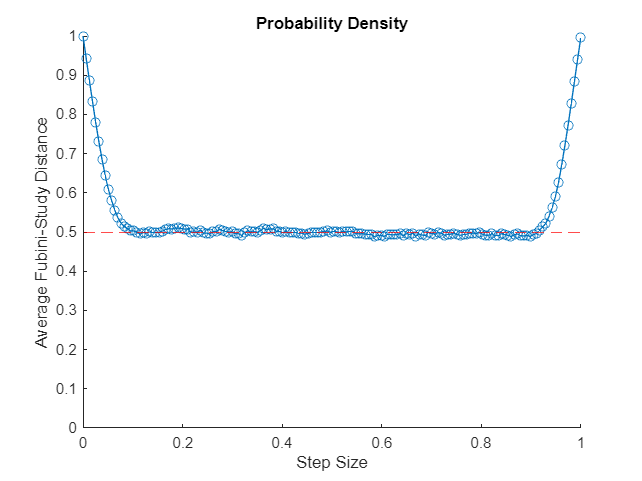

ans =     1.0000    0.9432    0.8876    0.8325    0.7803    0.7308    0.6850    0.6437    0.6090    0.5803    0.5560    0.5364    0.5224    0.5147    0.5087    0.5029    0.5026    0.4995    0.4950    0.4985    0.4973    0.5001    0.4991    0.4982    0.4991    0.5023    0.5058    0.5082    0.5076    0.5099    0.5103    0.5093    0.5075    0.5073    0.5000    0.5000    0.4999    0.5038    0.4975    0.4970    0.4953    0.5006    0.5019    0.5062    0.5040    0.5016    0.4998    0.5001    0.4957    0.4956


Number_of_Qubits = 1;
Number_of_Steps = 100;
Number_of_Walks = 1000; 
Step_Size = 0.01;

Random_Walk_Algorithm(Number_of_Qubits, Number_of_Steps, Number_of_Walks, Step_Size)


function RWA = Random_Walk_Algorithm(Number_of_Qubits, Number_of_Steps, Number_of_Walks, Step_Size)

    Dimensions = 2^Number_of_Qubits;
    Component_Volume = Number_of_Walks*Number_of_Steps;
    
    Pole_Vector = zeros(Dimensions, 1);
    Pole_Vector(1) = 1; 
    
    Vector_Database= randn(Dimensions, Component_Volume)+1i*randn(Dimensions, Component_Volume);
    
    Step_Sizes = 0:Step_Size:pi/2;
    numStepSizes = length(Step_Sizes);
    RWA = zeros(Number_of_Walks, numStepSizes);
    
    for i = 1:Number_of_Walks
        Index = 0;

        for j = Step_Sizes

            Index = Index + 1;
            Vectors(:,1) = Pole_Vector; 
        
            for k = 1:Number_of_Steps
                Selected_Vector = Vector_Database(:, k + (i-1)*Number_of_Steps);
                Orthogonal_Vector = Selected_Vector - dot(Vectors(:,k), Selected_Vector) * Vectors(:,k);
                Normalized_Vector = Orthogonal_Vector / norm(Orthogonal_Vector);
                

                Vectors(:,k+1) = (cos(j) * Vectors(:,k)) + (sin(j) * Normalized_Vector);
            end

            RWA(i, Index) = (2/pi)*Fubini_Study_Distance(Vectors(:,1), Vectors(:,Number_of_Steps+1));
        end            
    end 

    RWA = 1 - abs(mean(RWA, 1));

    figure;
    hold on
    plot(abs((2/pi)*Step_Sizes), RWA, 'o-');
    ylim([0, 1]);
    xlabel('Step Size');
    ylabel('Average Fubini-Study Distance');
    title('Probability Density');
    yline(0.5, '--r')
    hold off;

Data_File = fopen('ProbDens100M.txt', 'w');

for i = 1:length(Step_Sizes)
    fprintf(Data_File, "(%f,%f)\n", (2/pi)*Step_Sizes(i), RWA(i));
end

fclose(Data_File);

end

function FBS = Fubini_Study_Distance(Vector_1, Vector_2)

    FBS = acos(abs(dot(Vector_1,Vector_2)));
end